clear
load data5.mat
n=length(data.CzasLokalnyUTC0100)

n = 6960

data.CzasLokalnyUTC0100(1:4)

ans = 4×1 datetime array
   15.09.2025 12:00:00
   15.09.2025 12:01:00
   15.09.2025 12:02:00
   15.09.2025 12:03:00


data.CzasLokalnyUTC0100(n-3:n)

ans = 4×1 datetime array
   20.09.2025 07:56:00
   20.09.2025 07:57:00
   20.09.2025 07:58:00
   20.09.2025 07:59:00


We observe fs of 60s

From time vector:

T=60; %[s]
fs=1/T; %[Hz]
t_all=T*(0:n-1);

Kompresor1=data.StanKompresor;
StanCzujnikaZamkniecia=data.StanCzujnikZamkniciaDrzwi;



TemperaturaOtoczenia=0.1*data.TemperaturaOtoczenia;
Wlot=0.1*data.TemperaturaSterujca;


X=[Kompresor1,StanCzujnikaZamkniecia,...
    TemperaturaOtoczenia,Wlot]';

t=T*(1:n);
size(X)

ans =            4        6960


[dataWithoutNans,nan_indices]  = GetRidOfNans(X);
find(nan_indices,~0)


ans =

  0×1 empty double column vector



no nans

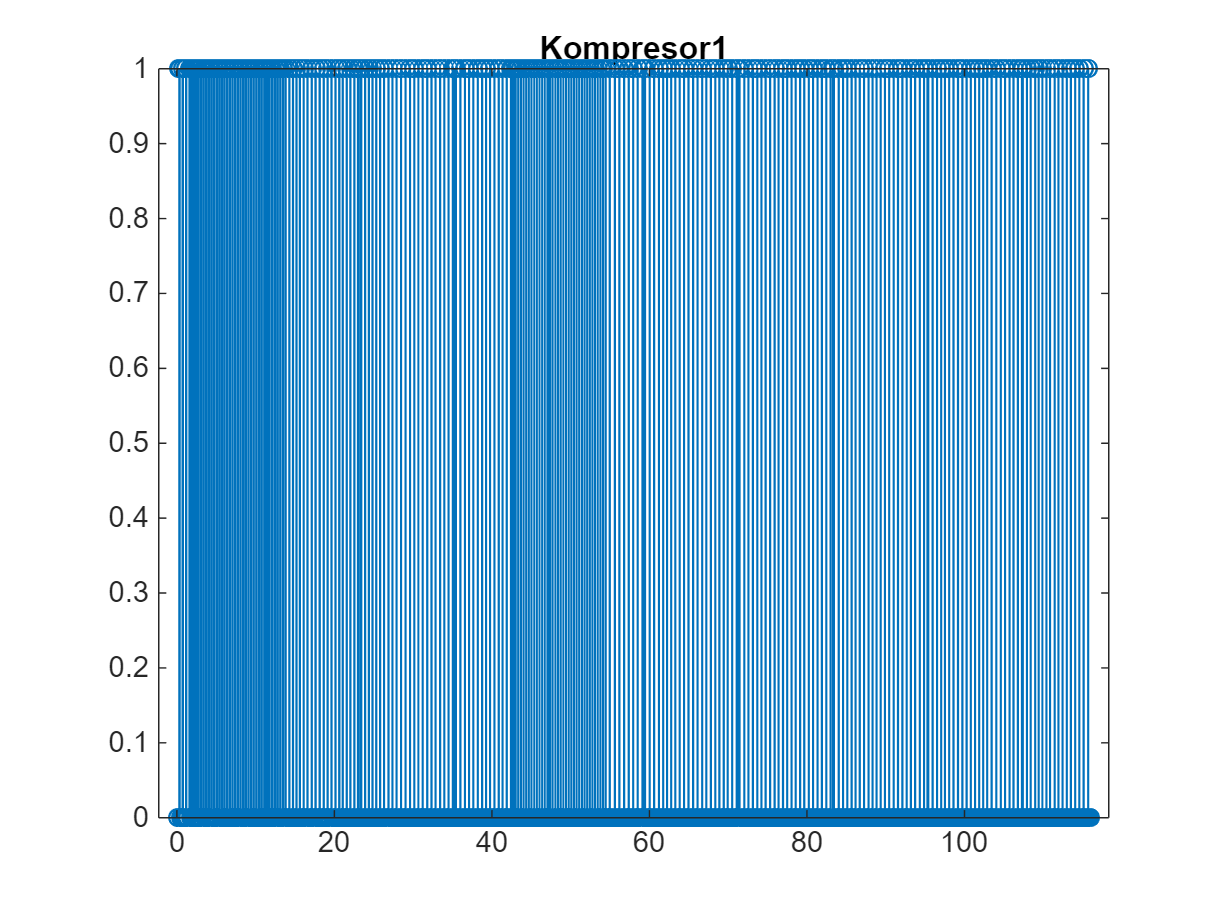

stem(t./(60*60),X(1,:))
title('Kompresor1')

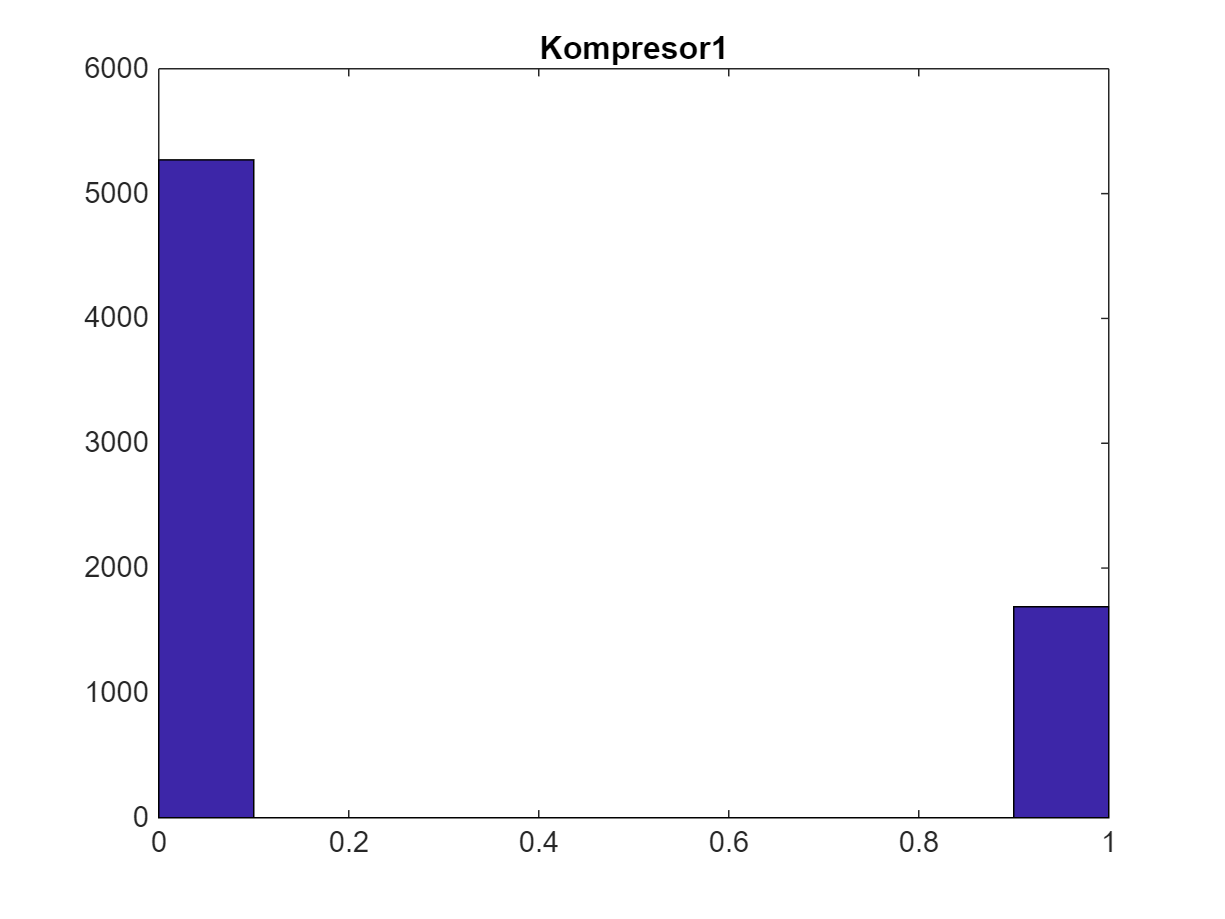

hist(X(1,:))
title('Kompresor1')

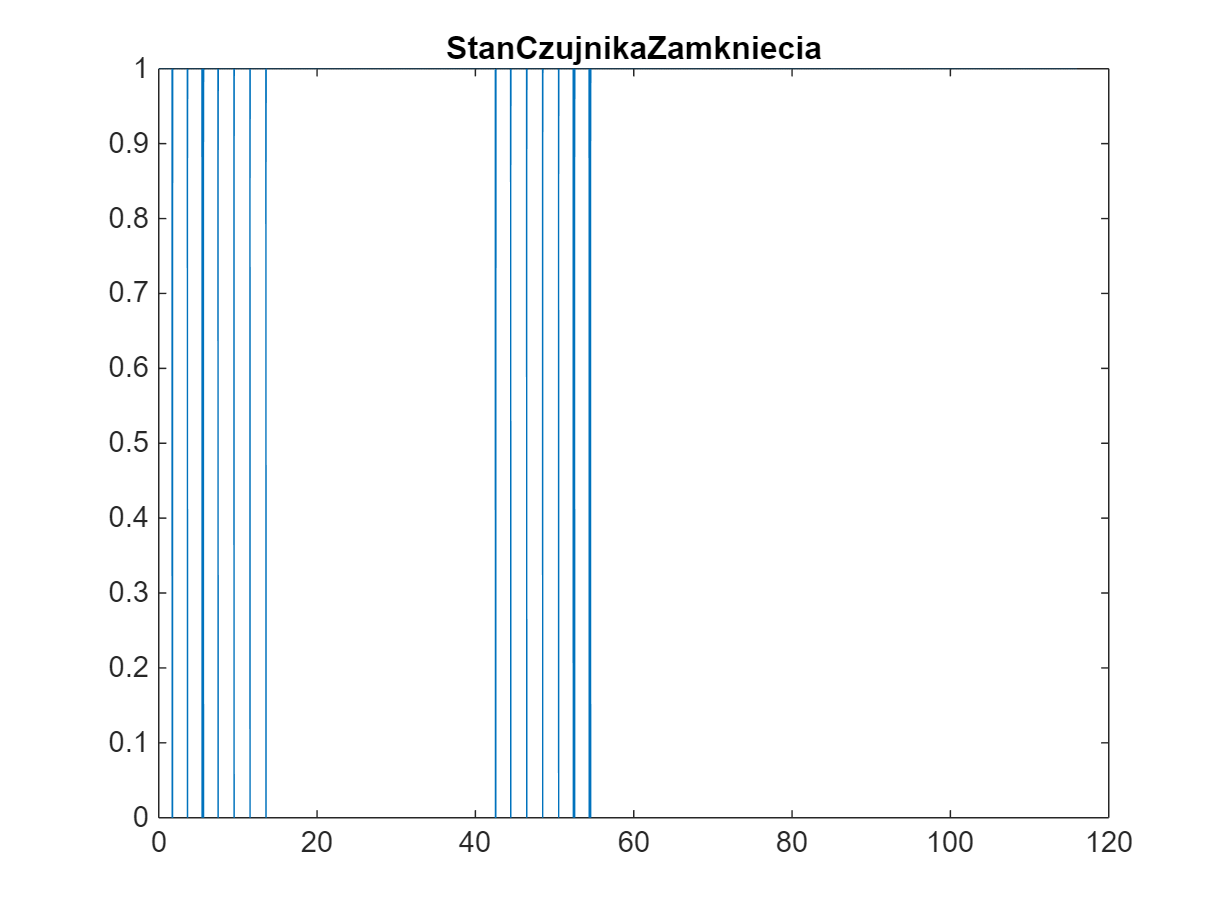

plot(t/(60*60),X(2,:))
title('StanCzujnikaZamkniecia')

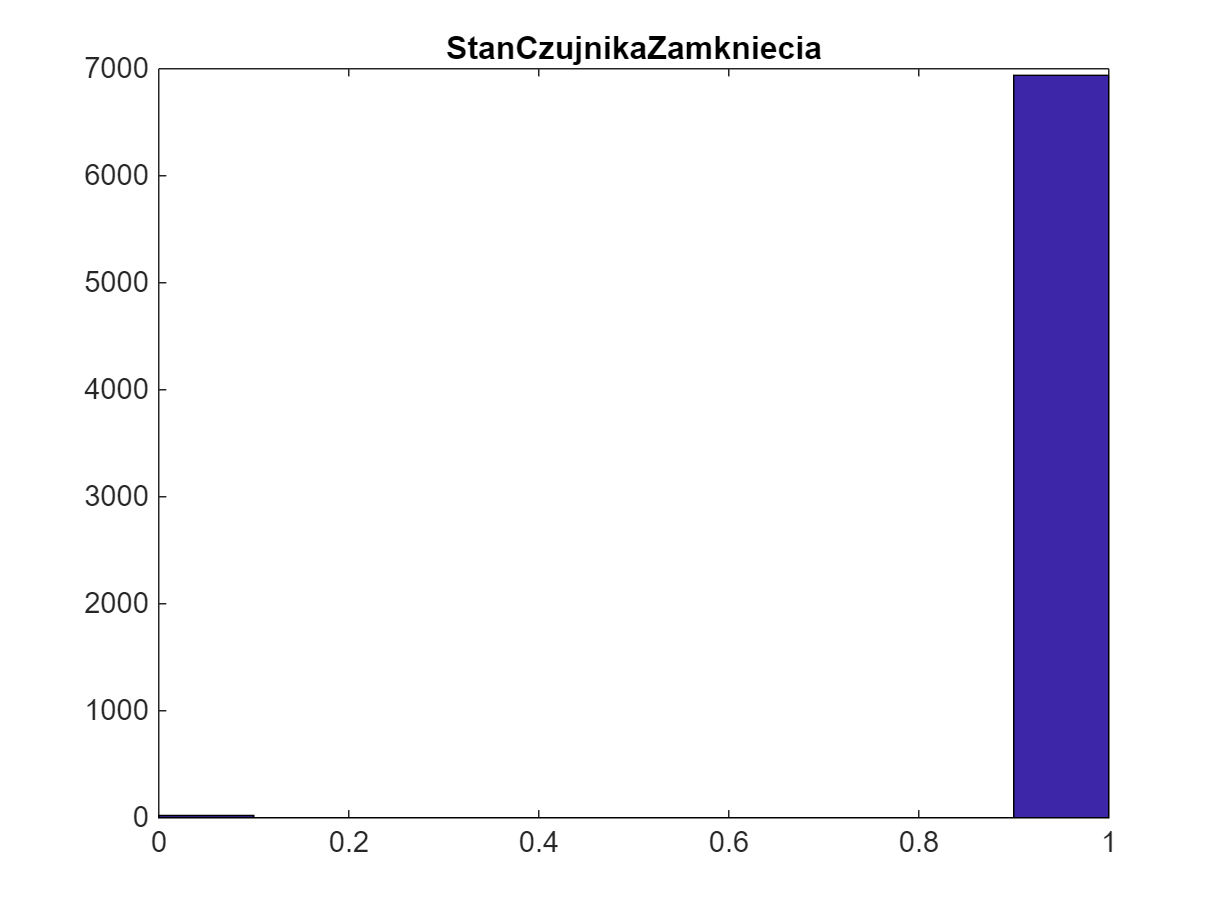

hist(X(2,:))
title('StanCzujnikaZamkniecia')

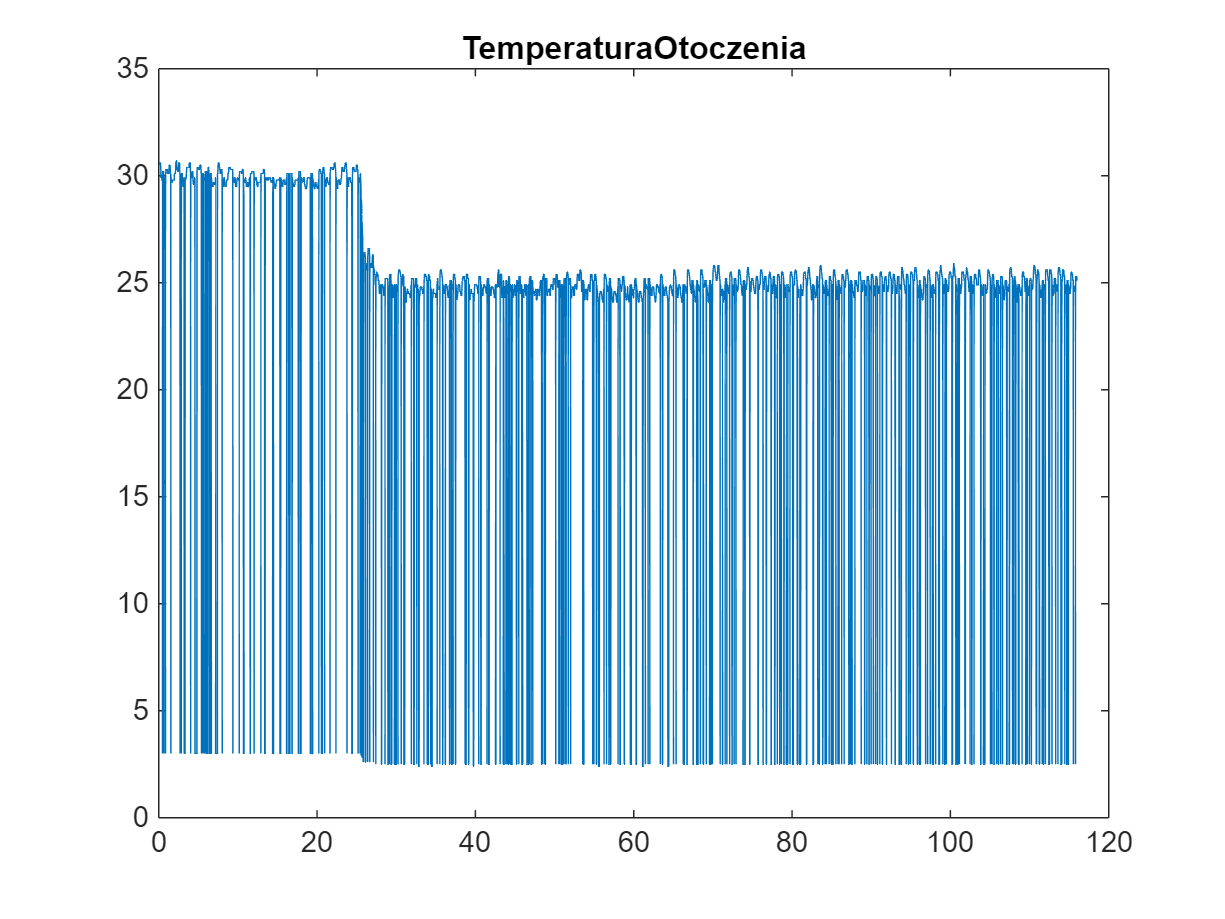

plot(t/(60*60),X(3,:))
title('TemperaturaOtoczenia')

We see measurement errors. We need to delete and interpolate values between 2 and 3.5 degrees

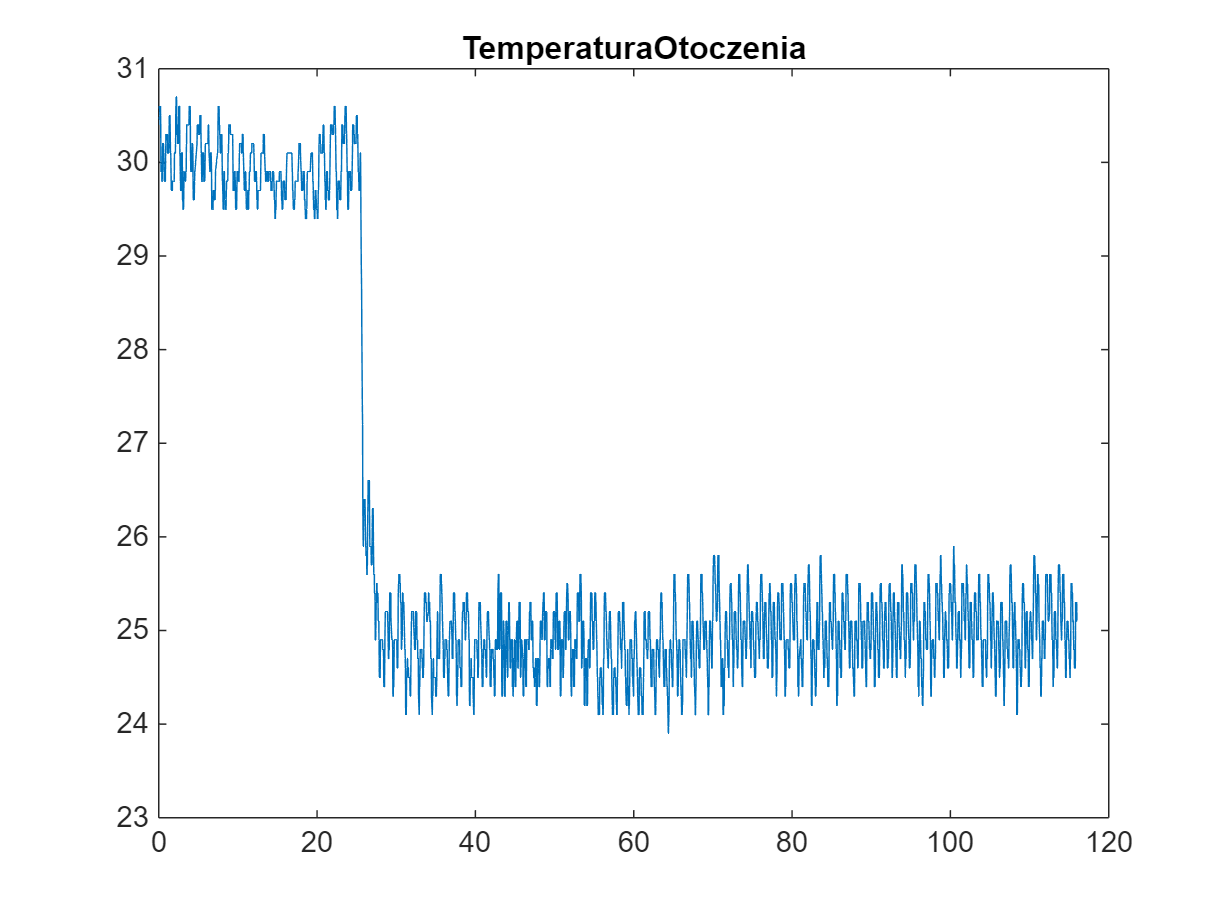

plot(t/(60*60),InterpolateData(X(3,:),[2,3.5],t_all))
title('TemperaturaOtoczenia')

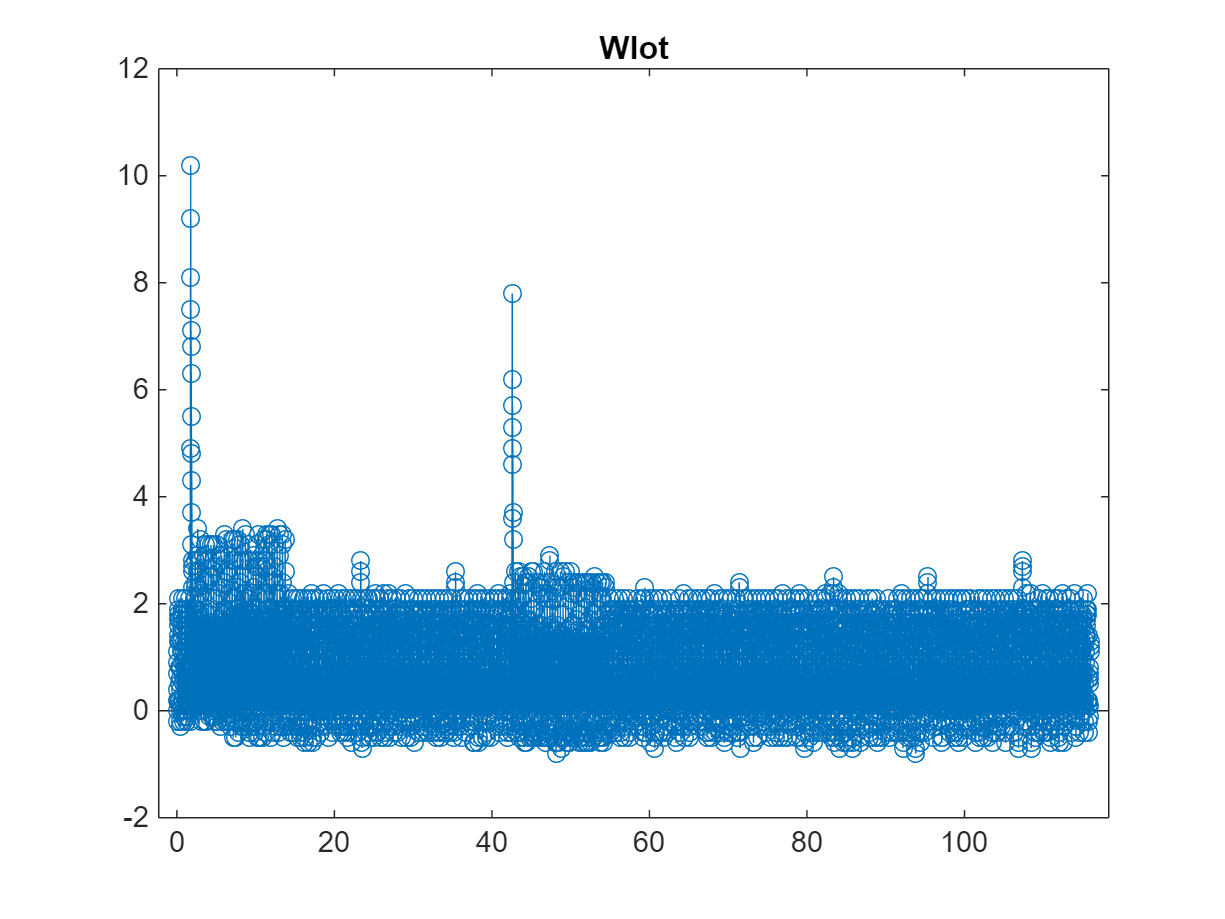

stem(t/(60*60),X(4,:))
title('Wlot')

errors between 0.05 and 0.15 degrees C

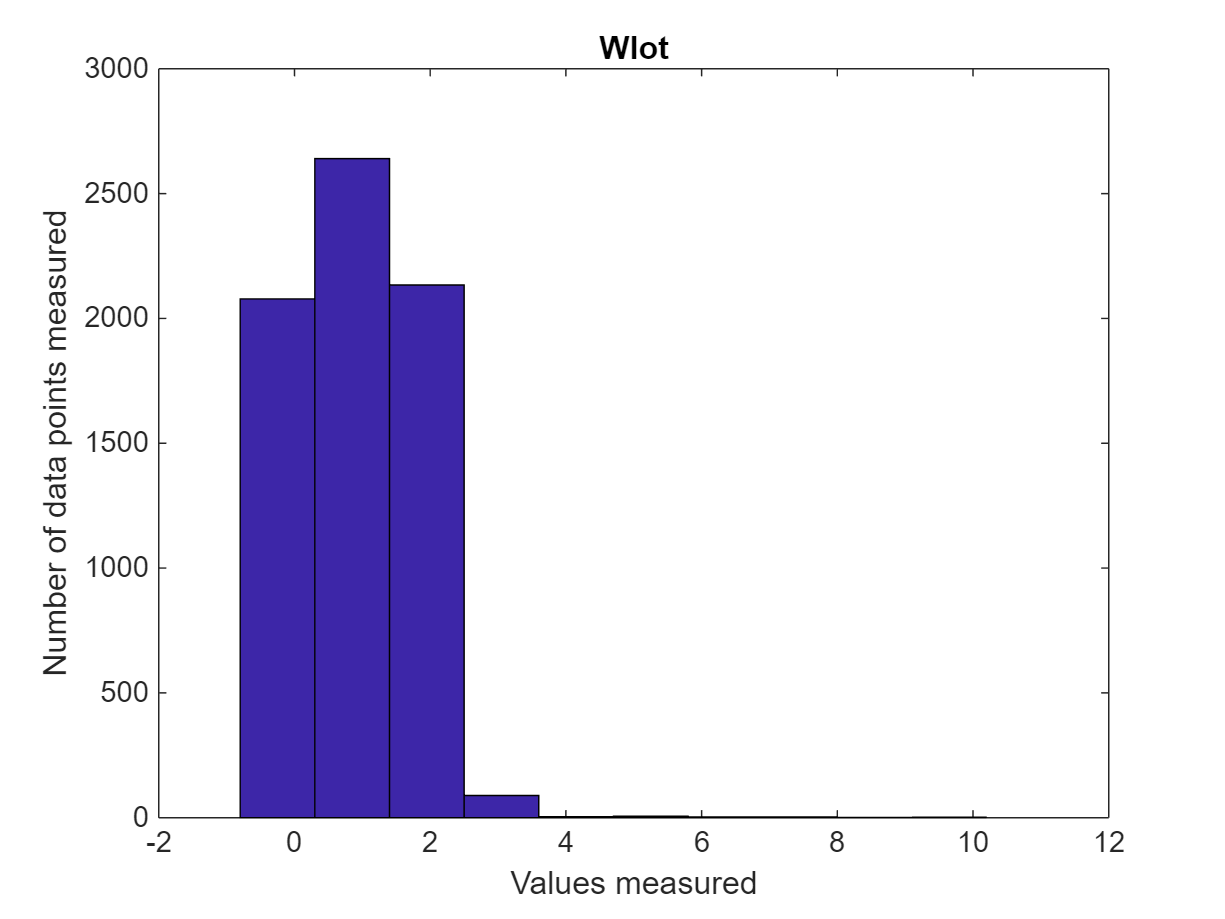

hist(X(4,:))
title('Wlot')
xlabel('Values measured')
ylabel('Number of data points measured')

test=InterpolateData(X(4,:),[0.005 0.15],t_all)

test =    -0.2000   -0.2000         0    0.2000    0.4000    0.7000    0.9000    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    0.2000    2.1000    0.2000    1.7000    1.3000    1.0500    0.8000    0.5000    0.2000         0   -0.2000   -0.3000   -0.2000         0    0.4000    0.6000    0.8000    0.9500    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    0.2000    2.1000    2.1000    1.8000    1.5000    1.1000    0.9000    0.6000    0.3000         0   -0.2000


test2=InterpolateData(test,[0.19 0.21],t_all)

test2 =    -0.2000   -0.2000         0    0.2000    0.4000    0.7000    0.9000    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    1.9000    1.7000    1.3000    1.0500    0.8000    0.5000    0.2500         0   -0.2000   -0.3000   -0.2000         0    0.4000    0.6000    0.8000    0.9500    1.1000    1.3000    1.4000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.1000    1.8000    1.5000    1.1000    0.9000    0.6000    0.3000         0   -0.2000


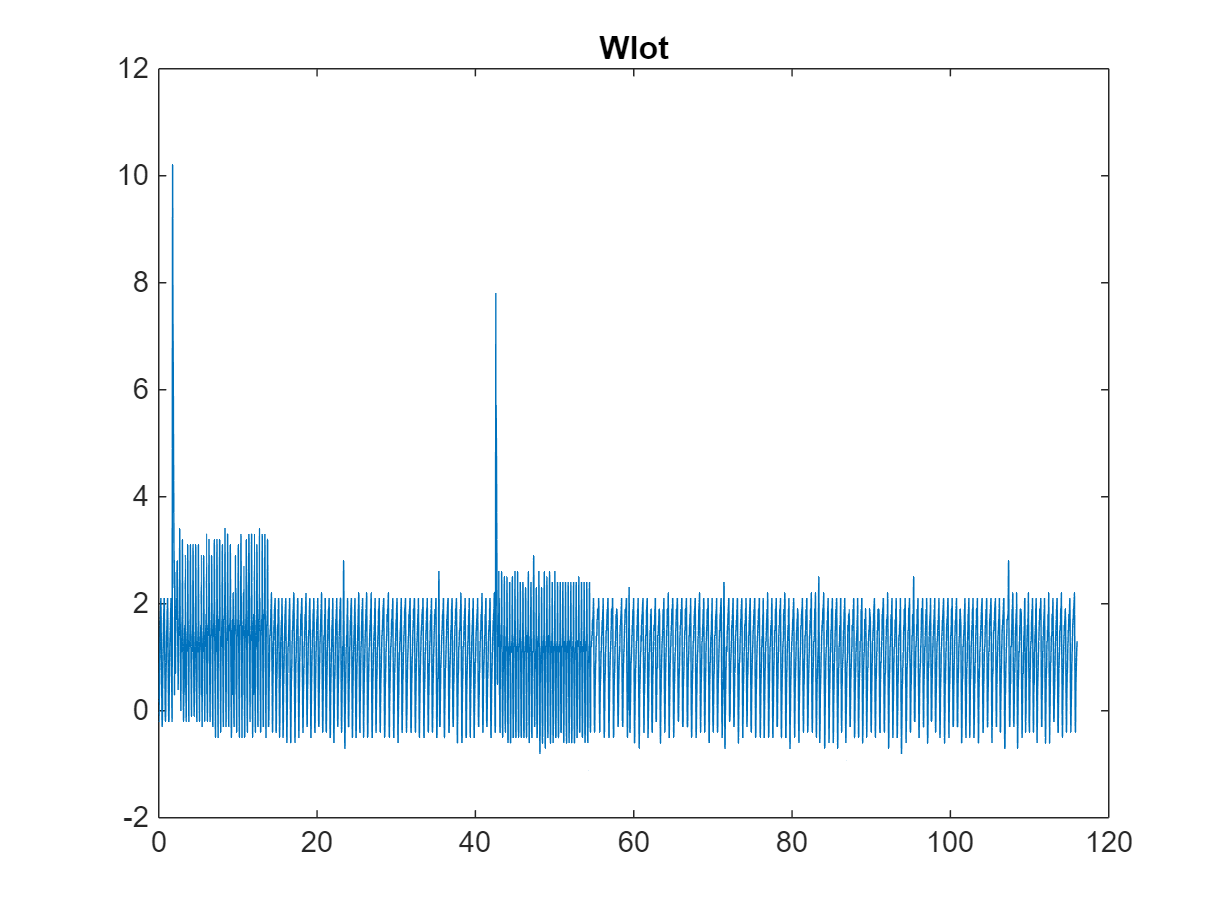

plot(t/(60*60),test2)
title('Wlot')